# Defining transfer functions in MATLAB and computing poles

Assume that the transfer function is already known and we want to enter this into MATLAB; this file gives a number of examples. Similarly, at times the transfer function could have been auto-generated, and subsequently we want to know what are the coefficients or where are the poles and zeros. We illustrate the ***tfdata.m, zpkdata.m*** and ***pzmap.m*** files for computing these. 

You will need the control toolbox for this file.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter (University of Sheffield) and  Ruth Bars (Budapest University of Technology and Economics)                                 

## Table of contents

- Examples of how to create a transfer function using three alternatives

- Examples of higher order transfer functions

- Example of a transfer function with zero coefficients

- Extracting numerator and denominator coefficients or poles and zeros from a transfer function model

- Computing poles and zeros from the transfer function

## 1. Examples of how to create a transfer function using 3 alternatives  

Modify the code in the lines below to change the examples and press 'run section' to activate yoru choice.

### 1.1. Using the file tf.m

The file ***tf.m*** takes as arguments the coefficients of the numerator and denominator to create a transfer function object. This will be clear from several examples

$G\left(s\right)=\frac{1}{s^2 +5s+6};\;$has numerator with coefficient 1 and denominator with coefficients 1, 5 and 6

G=tf(1,[1 5 6])

MATLAB allocates the coefficients to powers of 's' in order, beginning from lowest power on the right.

### 1.2. Using the file zpk.m

Alternatively, with file ***zpk.m*** the transfer function can be built based on knowledge of the gain, zeros and poles.

$\textrm{G1}\left(s\right)=\frac{1}{\left(s+2\right)\left(s+3\right)};\;$has gain 1, has no zeros and the poles are -1 and -2.

disp('Section 1.2 below here: ******************************************************')

G =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


G1=zpk([],[-2 -3],1)

Both the tf and zpk model forms can be converted to each other, that is, one can decide whether it is more convenient to express the transfer function in terms of its coefficients or its poles and zeros.

H=zpk(G)

Section 1.2 below here: ******************************************************


H1=tf(G1)

G1 =
 
       1
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties


### 1.3. Using symbolic variables

The transfer function can be defined even more directly by symbolic data entry. The Laplace **s** variable can be given by a special command

disp('Section 1.3 below here: ******************************************************')

H =
 
       1
  -----------
  (s+3) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


s=tf('s')

H1 =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


Then the transfer function G is defined directly by writing in terms of this symbolic variable.

Gtf=1/(s^2+5*s+6)

Section 1.3 below here: ******************************************************


If the Laplace **s** variable is given in the form:

s=zpk('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Then the transfer function is obtained in zpk form:

Gzpk=1/(s^2+5*s+6)

Gtf =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


The advantage of these forms is that operations with the transfer functions can be executed easily. 

### 1.4. More detailed functionality

Users can type: ***help tf*** or*** help zpk*** to find out more about these functions and their additional functionality.

## 2. Examples of higher order transfer functions

We use the same 3 methods as given in section 1, but now apply to some higher order examples.

disp('Section 2 below here: ******************************************************')

s =
 
  s
 
Continuous-time zero/pole/gain model.
Model Properties


### 2.1 Using tf.m

Look at his higher order example and see how MATLAB automatically allocates the powers of 's' corresponding to the order in which the coefficients are supplied. 

$\textrm{G2}\left(s\right)=\frac{s^2 +0\ldotp 1s+4}{{5s^3 +2s}^2 -4s+6\ldotp 3};\;$has numerator with coefficients 1, 0.1 and 4 and denominator with coefficients 5, 2, -4 and 6.3.

G2=tf([1 0.1 4],[5 2 -4 8.3])

Gzpk =
 
       1
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties


### 2.2. Using  zpk.m

Take a high order example with multiple poles and zeros.

$\textrm{G3}\left(s\right)=\frac{2\ldotp 3\left(s+4\right)}{s\left(s+2\right)\left(s+3\right)\left(s-1\right)}$.

disp('Section 2.2 below here: ******************************************************')

Section 2 below here: ******************************************************


G3=zpk([-4],[0,-2, -3,1],2.3)

Both the tf and zpk model forms can be converted to each other, that is, one can decide whether it is more convenient to express the transfer function in terms of its coefficients or its poles and zeros. Note *H2* has a quadratic factor (complex poles).

H2=zpk(G2)

G2 =
 
       s^2 + 0.1 s + 4
  -------------------------
  5 s^3 + 2 s^2 - 4 s + 8.3
 
Continuous-time transfer function.
Model Properties


H3=tf(G3)
poles_of_G2=pzmap(G2)

### 2.3. Using symbolic variables

The transfer function can be defined even more directly by symbolic data entry, although this may be less convenient in the long term when transfer functions are created directly from within code, or for high order transfer functions. 

disp('Section 2.3 below here: ******************************************************')

Section 2.2 below here: ******************************************************


s=tf('s')

G3 =
 
       2.3 (s+4)
  -------------------
  s (s+2) (s+3) (s-1)
 
Continuous-time zero/pole/gain model.
Model Properties


Then the transfer function G is defined directly by writing in terms of this symbolic variable.

Gtf2=(s^2+0.1*s+4)/(5*s^3+2*s^2-5*s+6.3)

H2 =
 
        0.2 (s^2 + 0.1s + 4)
  --------------------------------
  (s+1.576) (s^2 - 1.176s + 1.053)
 
Continuous-time zero/pole/gain model.
Model Properties


## 3. Example of a transfer function with zero coefficients

What if some of the coefficients are zero? Simple, just include zeros in the coefficients that you supply.

$\textrm{G4}\left(s\right)=\frac{s^3 -0\ldotp 4s+5\ldotp 8}{{2\ldotp 1s^4 +7s}^2 +4\ldotp 2s};\;$note this has no $s^2$ in the numerator and no $s^3$ and $s^0$ in the denominator so we put zeros in those positions in the tf.m call line below.

disp('Section 3 below here: ******************************************************')

H3 =
 
        2.3 s + 9.2
  -----------------------
  s^4 + 4 s^3 + s^2 - 6 s
 
Continuous-time transfer function.
Model Properties


G4=tf([1 0 -0.4 5.8],[2.1 0 7 4.2 0])

poles_of_G2 =   -1.5760 + 0.0000i
   0.5880 + 0.8412i
   0.5880 - 0.8412i


**NOTE**: When expressing systems in terms of their zeros, poles and gain, the zero coefficients will not be evident so this subtlety is not important.

## 4. Extracting numerator and denominator coefficients or poles and zeros from a transfer function model

It may be that the transfer function has been defined elsewhere and you want to know exactly what the coefficients/poles/zeros are. MATLAB has a simple tools for this.

### 4.1 Extracting the numerator and denominator coefficients

For models defined in the tf format, the file called*** tfdata.m ****can be used.* The built in help will give more detail so we illustrate just one simple case. Note how the two vectors are of the same length so with strictly proper transfer functions the numerator vector will have some leading zeros.

disp('Section 4 below here: ******************************************************')

Section 2.3 below here: ******************************************************


disp('BELOW ARE EXAMPLES OF HOW TO EXTRACT NUMERATOR/DENOMINATOR COEFFICIENTS')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


G5=tf([1 4 2],[1 0 3 5])
[n,d]=tfdata(G5,'v')    % without the 'v' option, values returned as cell arrays

Gtf =
 
       s^2 + 0.1 s + 4
  -------------------------
  5 s^3 + 2 s^2 - 5 s + 6.3
 
Continuous-time transfer function.
Model Properties


H =tf(3,[1 -3 -5])
[nH,dH] = tfdata(H,'v')

### 4.2 Extracting the zero/pole/gain data from a zpk format

For models defined in the zpk format, the file called***  zpkdata.m ***can be used to extract the poles, zeros and gain*.* The built in help will give more detail so we illustrate just one simple case.

disp('Section 4.2 below here: ******************************************************')

Section 3 below here: ******************************************************


G6=zpk([-4],[0,-2, -3,1],2.3)

G4 =
 
     s^3 - 0.4 s + 5.8
  -----------------------
  2.1 s^4 + 7 s^2 + 4.2 s
 
Continuous-time transfer function.
Model Properties


[z,p,k]=zpkdata(G6,'v')    % without the 'v' option, values returned as cell arrays


## 5. Computing poles and zeros from the transfer function

The poles and zeros can also be computed using the pzmap.m file.  Depending on how the statement is used you will either:

- Get numerical values into the workspace.

- A plot showing poles with 'X' and zeros with 'O'.

#### Compute the numerical values of poles and zeros

disp('SECTION 5 BELOW ARE POLE-ZERO COMPUTATIONS')

Section 4 below here: ******************************************************


[Gpoles, Gzeros]=pzmap(G)

BELOW ARE EXAMPLES OF HOW TO EXTRACT NUMERATOR/DENOMINATOR COEFFICIENTS


[G2poles, G2zeros]=pzmap(G2)

G5 =
 
  s^2 + 4 s + 2
  -------------
  s^3 + 3 s + 5
 
Continuous-time transfer function.
Model Properties


[G3poles, G3zeros]=pzmap(G3)

n =      0     1     4     2


d =      1     0     3     5


H =
 
        3
  -------------
  s^2 - 3 s - 5
 
Continuous-time transfer function.
Model Properties


#### Plot the poles and zeros on an Argand diagram

figure

nH =      0     0     3


dH =      1    -3    -5


pzmap(G)
title('Pole-zero map for G(s)')
figure

Section 4.2 below here: ******************************************************


pzmap(G2)

G6 =
 
       2.3 (s+4)
  -------------------
  s (s+2) (s+3) (s-1)
 
Continuous-time zero/pole/gain model.
Model Properties


title('Pole-zero map for G2(s)')

z = -4

p =      0
    -2
    -3
     1


k = 2.3000

SECTION 5 BELOW ARE POLE-ZERO COMPUTATIONS


Gpoles =    -3.0000
   -2.0000



Gzeros =

  0×1 empty double column vector



G2poles =   -1.5760 + 0.0000i
   0.5880 + 0.8412i
   0.5880 - 0.8412i


G2zeros =   -0.0500 + 1.9994i
  -0.0500 - 1.9994i


G3poles =      0
    -2
    -3
     1


G3zeros = -4

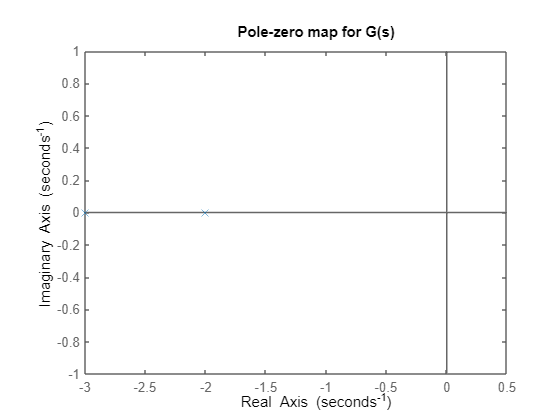

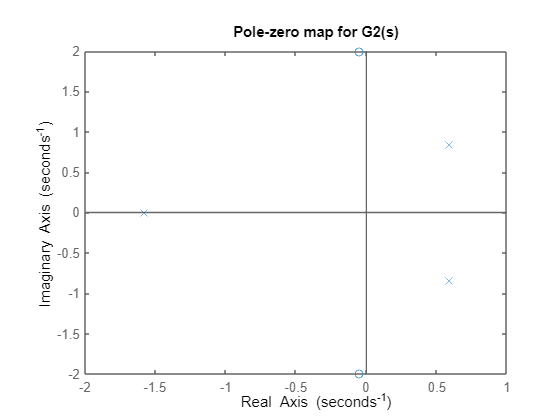

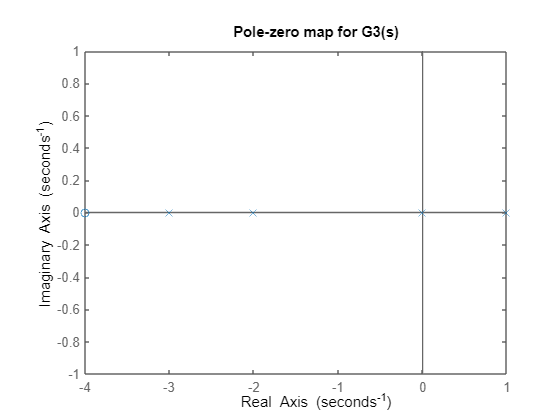

figure
pzmap(G3)
title('Pole-zero map for G3(s)')